# Task 1 – binary morphology versus region growing

***Questions in 'Final_Task1_tcg' file***

## First domain - Dog sprinting

First we read the two images. We shrink their size by half, so as to quicken the segmentation process.

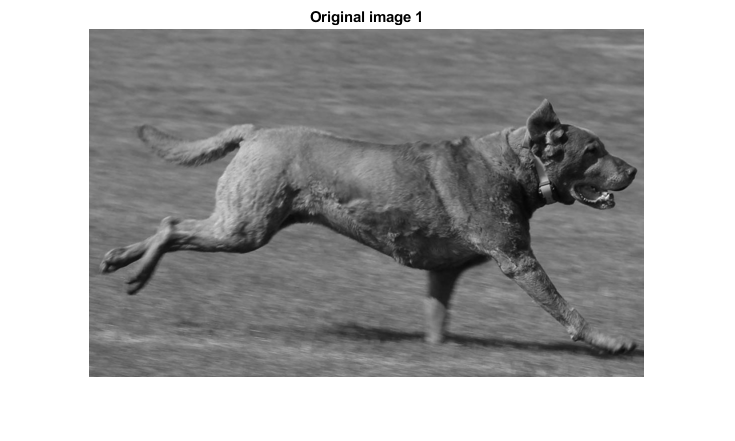

img_path = "images/final/task_1/";

image1 = imread(img_path + "dog_1.jpg");
img1small = imresize(image1, 0.5);

image2 = imread(img_path + "dog_2.jpeg");
img2small = imresize(image2, 0.5);

img1gray = rgb2gray(img1small);
img2gray = rgb2gray(img2small);

img1bw = imbinarize(img1gray);
img2bw = imbinarize(img2gray);

imshow(img1gray);
title('Original image 1')

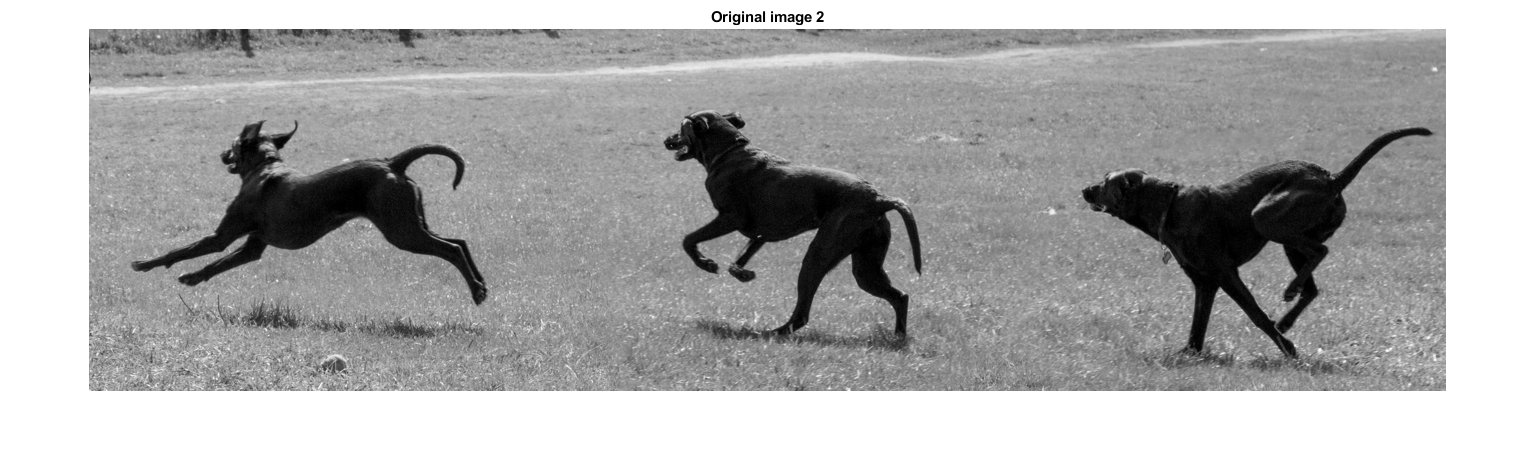

imshow(img2gray);
title('Original image 2')

We would like to extract the dogs from the images.

### Region growing

#### First image

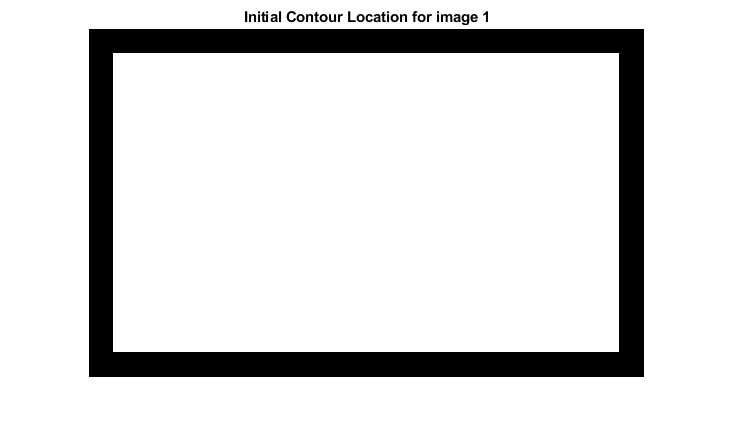

mask1 = zeros(size(img1gray));
mask1(25:end-25,25:end-25) = 1;
imshow(mask1)
title('Initial Contour Location for image 1')

bw1snake = activecontour(img1gray, mask1, 2000);

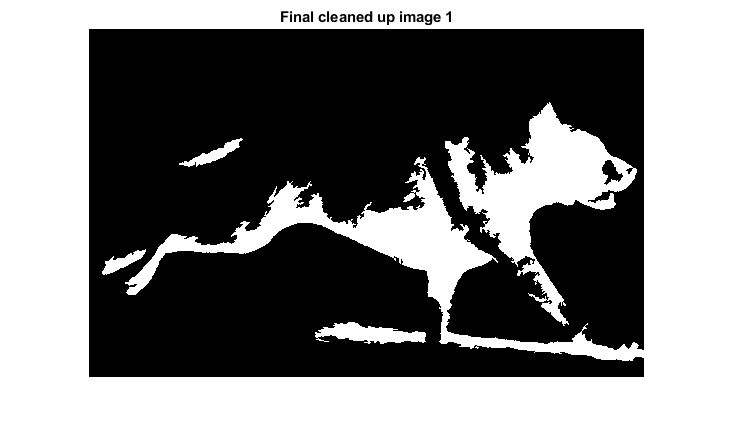

bw1snakeFinal = bwareaopen(bw1snake, 300);
imshow(bw1snakeFinal)
title('Final cleaned up image 1')

#### Second image

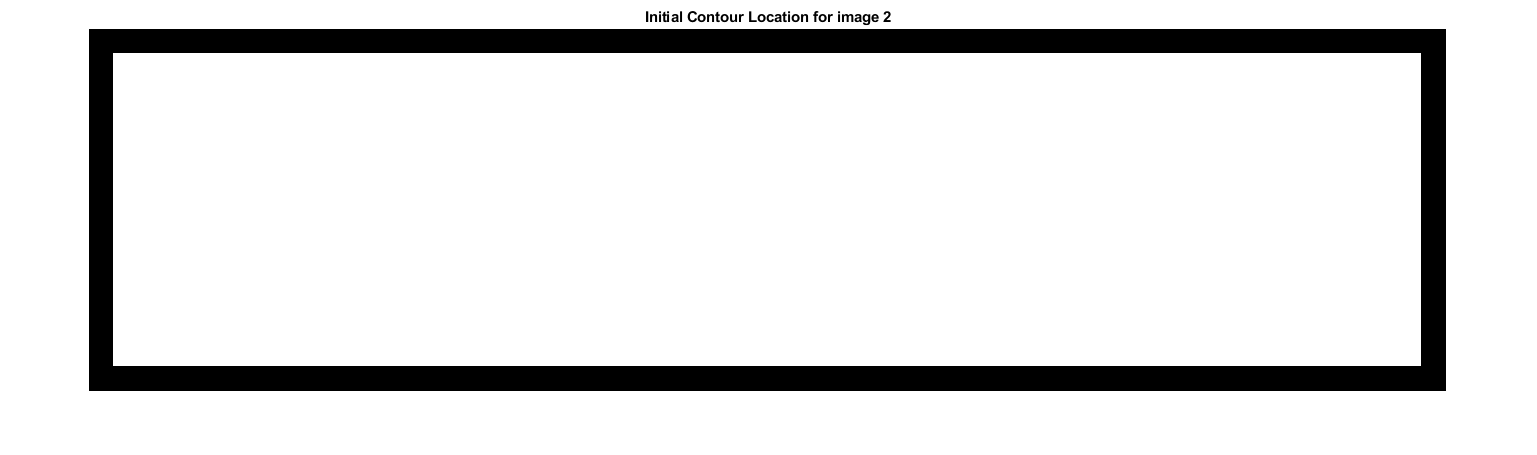

mask2 = zeros(size(img2gray));
mask2(25:end-25,25:end-25) = 1;
imshow(mask2)
title('Initial Contour Location for image 2')

bw2snake = activecontour(img2gray, mask2, 2000);

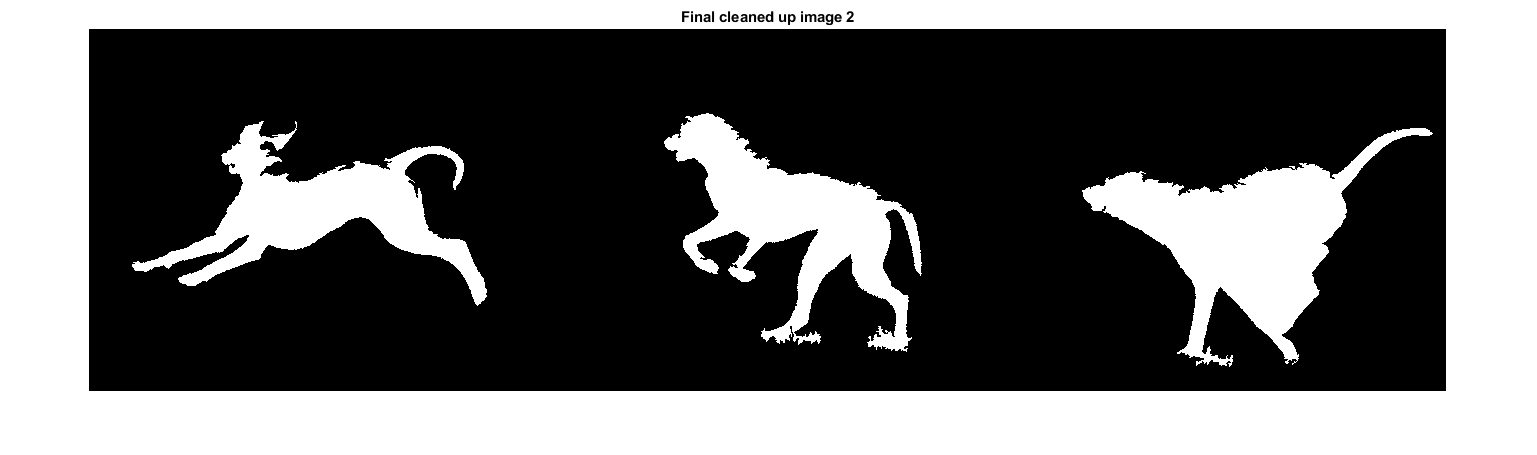

bw2snakeFinal = bwareaopen(bw2snake, 600);
imshow(bw2snakeFinal)
title('Final cleaned up image 2')

### Morphological operators

**For this step, a square structuring element that is 10 pixels wide will be used.**

#### First image

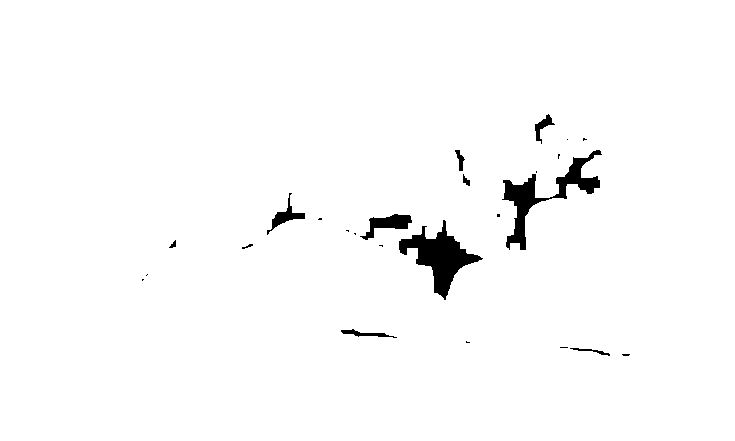

se = strel('square',10);
bw1morphDil = imdilate(img1bw, se);
imshow(bw1morphDil);

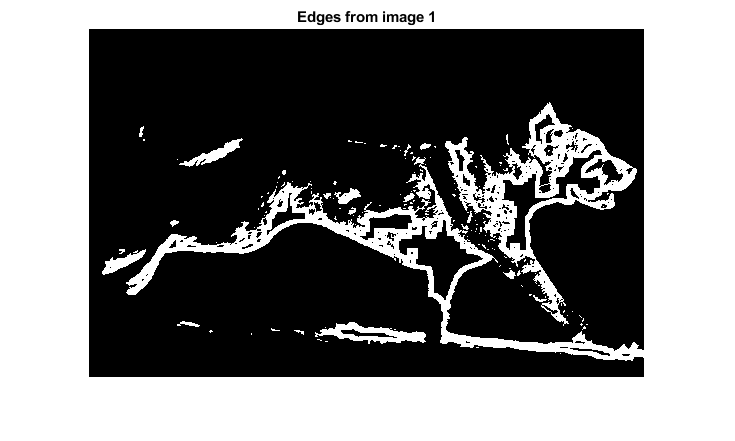

img1edges = imsubtract(bw1morphDil, img1bw);
imshow(img1edges);
title('Edges from image 1')

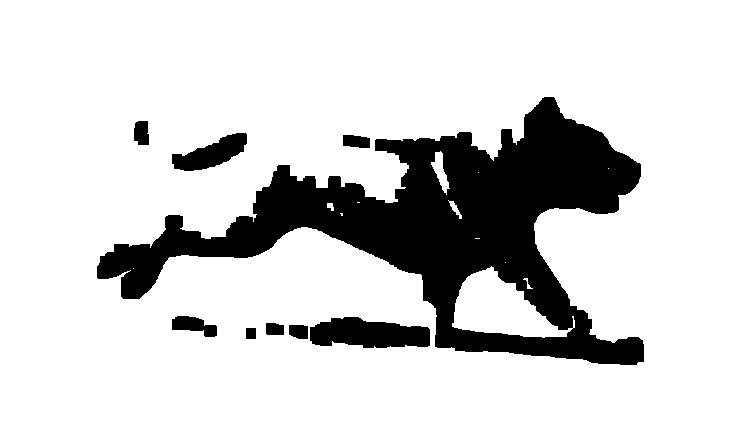

bw1morphEro = imerode(img1bw, se);
imshow(bw1morphEro);

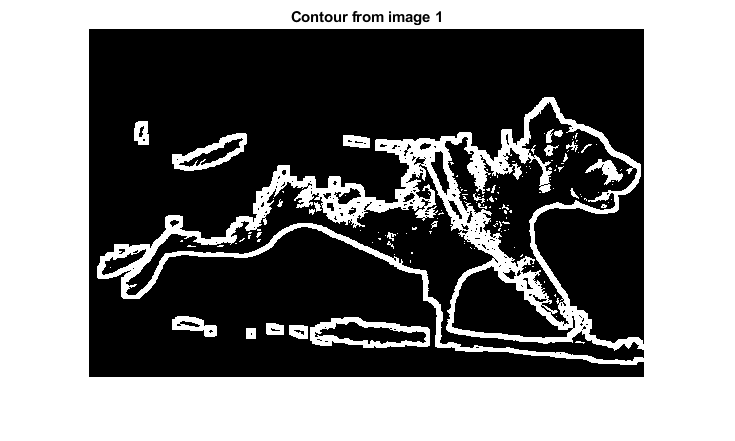

img1contour = imsubtract(img1bw, bw1morphEro);
imshow(img1contour);
title('Contour from image 1')

Here we have the cleaned up versions.

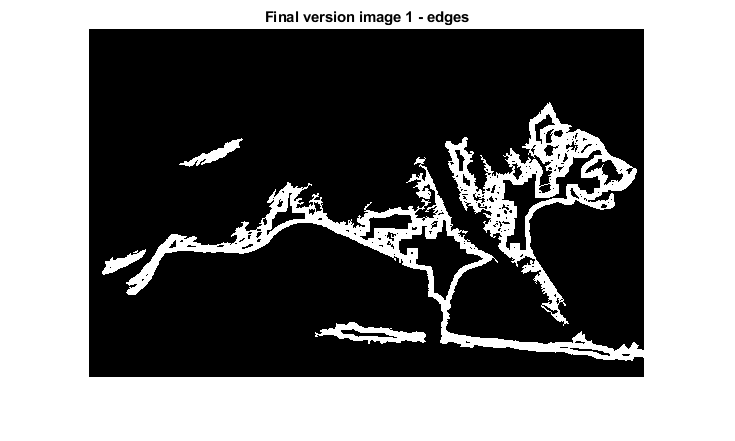

img1edgesFinal = bwareaopen(img1edges, 300);
imshow(img1edgesFinal); title('Final version image 1 - edges') 

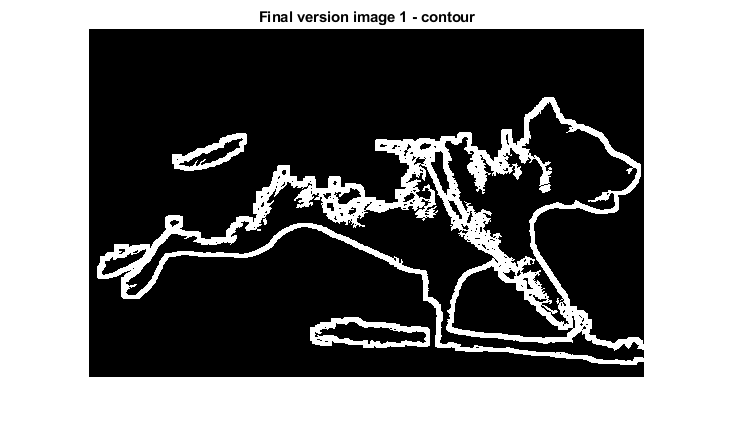

img1contourFinal = bwareaopen(img1contour, 500);
imshow(img1contourFinal); title('Final version image 1 - contour');

#### Second image

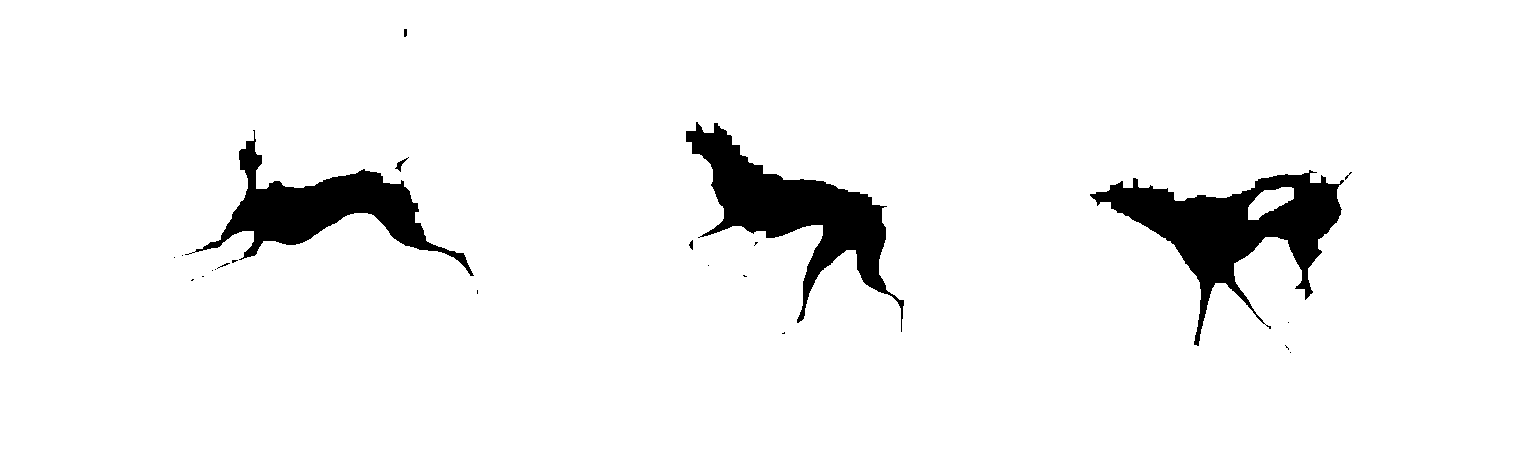

se = strel('square',10);
bw2morphDil = imdilate(img2bw, se);
imshow(bw2morphDil);

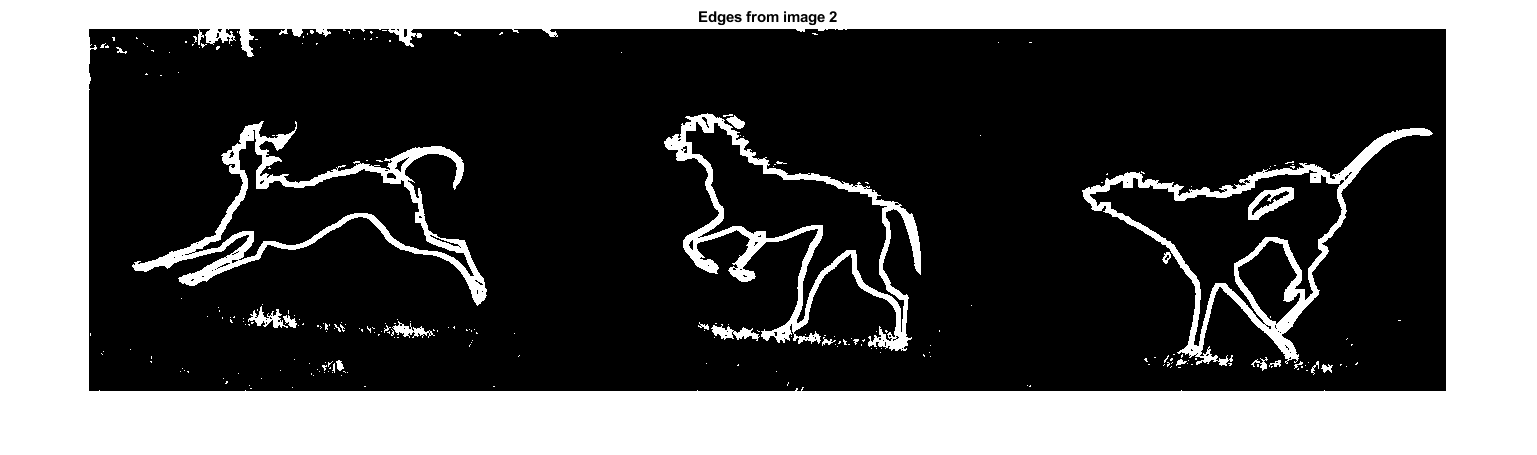

img2edges = imsubtract(bw2morphDil, img2bw);
imshow(img2edges);
title('Edges from image 2')

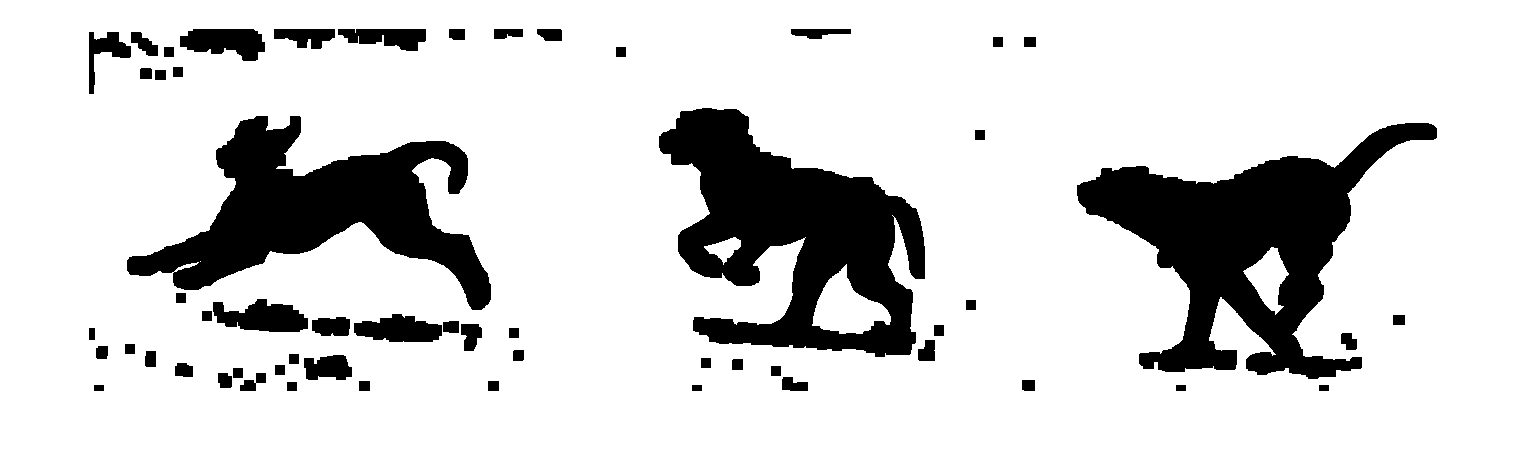

bw2morphEro = imerode(img2bw, se);
imshow(bw2morphEro);

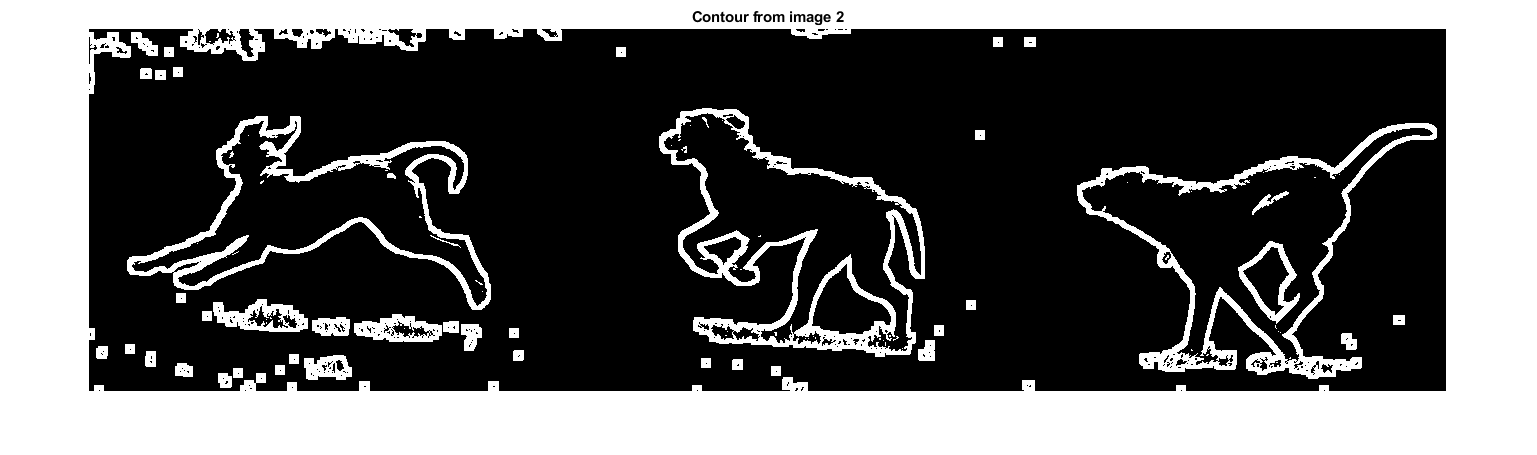

img2contour = imsubtract(img2bw, bw2morphEro);
imshow(img2contour);
title('Contour from image 2')

Here we have the cleaned up versions.

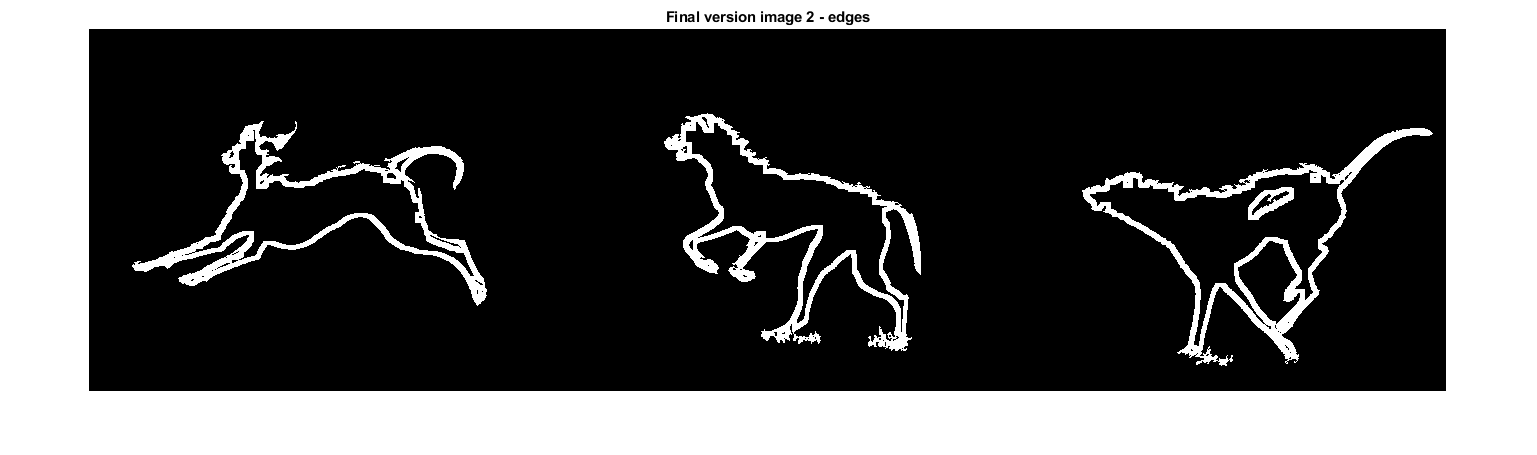

img2edgesFinal = bwareaopen(img2edges, 600);
imshow(img2edgesFinal); title('Final version image 2 - edges')

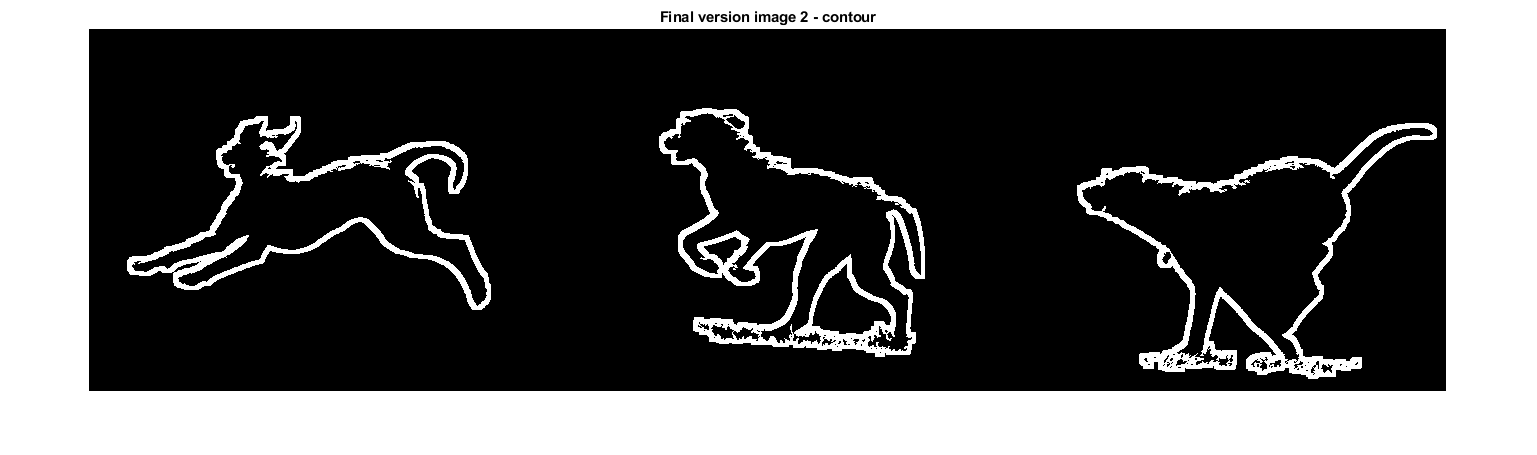

img2contourFinal = bwareaopen(img2contour, 1650);
imshow(img2contourFinal); title('Final version image 2 - contour');

## Conclusion

In terms of performance, the morphological operators execute way faster compared to region growing. We needed to shrink the size of the pictures so that the region growing algorithm finished faster.

Both morphological operators and region growing offers satisfactory results. Region growing ends with the silhouette of the dogs, while the morphological operators achieve the contour of the dogs.

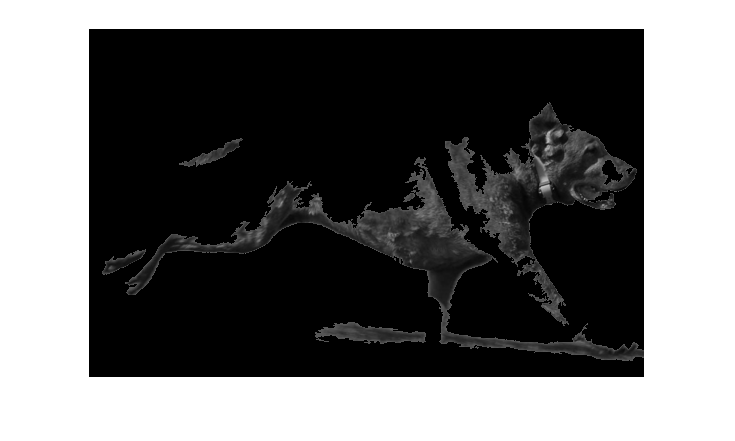

img1gray(~bw1snakeFinal) = 0;
imshow(img1gray);

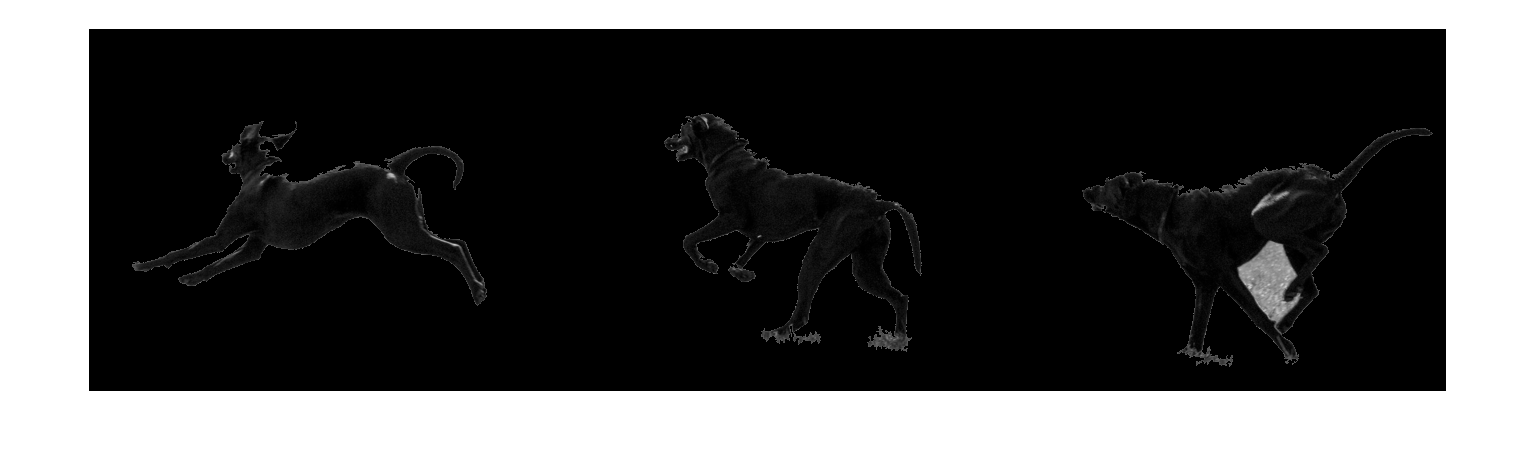

img2gray(~bw2snakeFinal) = 0;
imshow(img2gray);